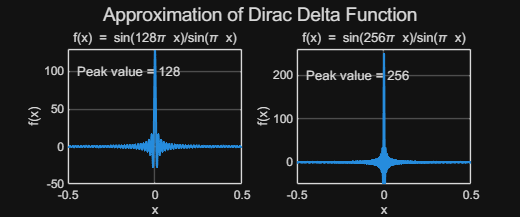

% Plot the function f(x) = sin(Nπx)/sin(πx) for N = 128 and N = 256
% This function demonstrates how f(x) approximates the Dirac delta function

% Define the parameters
N1 = 128;
N2 = 256;
x = linspace(-0.5, 0.5, 1000); % Create 1000 points in the interval [-1/2, 1/2]

% Calculate f(x) for both N values
% Handle the singularity at x = 0 separately
f1 = zeros(size(x));
f2 = zeros(size(x));

for i = 1:length(x)
    if abs(x(i)) < 1e-10  % For x very close to 0
        f1(i) = N1;       % Limit value at x = 0
        f2(i) = N2;
    else
        f1(i) = sin(N1*pi*x(i))/sin(pi*x(i));
        f2(i) = sin(N2*pi*x(i))/sin(pi*x(i));
    end
end

% Create a figure with two subplots
figure('Position', [100, 100, 1200, 500]);

% Plot for N = 128
subplot(1, 2, 1);
plot(x, f1, 'LineWidth', 1.5);
grid on;
title(['f(x) = sin(', num2str(N1), '\pi x)/sin(\pi x)']);
xlabel('x');
ylabel('f(x)');
axis([-0.5 0.5 -50 130]);

% Plot for N = 256
subplot(1, 2, 2);
plot(x, f2, 'LineWidth', 1.5);
grid on;
title(['f(x) = sin(', num2str(N2), '\pi x)/sin(\pi x)']);
xlabel('x');
ylabel('f(x)');
axis([-0.5 0.5 -50 260]);

% Add a suptitle (main title) for the entire figure
sgtitle('Approximation of Dirac Delta Function', 'FontSize', 14);

% Optional: Add text explaining key properties
text(-0.45, 100, ['Peak value = ', num2str(N1)], 'Parent', subplot(1,2,1));
text(-0.45, 200, ['Peak value = ', num2str(N2)], 'Parent', subplot(1,2,2));